# Actividad 5.1 (Control de Posición)

Elaborado por: Marcos Allen Martínez Cortés   |   A01737939

**Generar **un reporte de los pasos para poder obtener el control de posición en las coordenadas deseadas (**Descrito en el punto 3**) y plantear una estrategia para generar un controlador de ganancias auto-sintonizable.

%Limpieza de pantalla
clear all
close all
clc

Asignamos los valores del tiempo de la simulación, así como el tiempo de muestreo.

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=10;             % Tiempo de simulación en segundos (s)
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

Establecemos las condiciones iniciales (pose inicial del robot), las cuales se utilizarán para la localización, con la técnica de dead reckoning.

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=pi/2; %Orientación inicial del robot 

Establecemos las coordenadas deseadas.

%3 POSICION DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestra posición deseada
hxd=-7;
hyd=-7;

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

Para el diseño del algoritmo de control se utiliza la teoría de Lyapunov, donde:

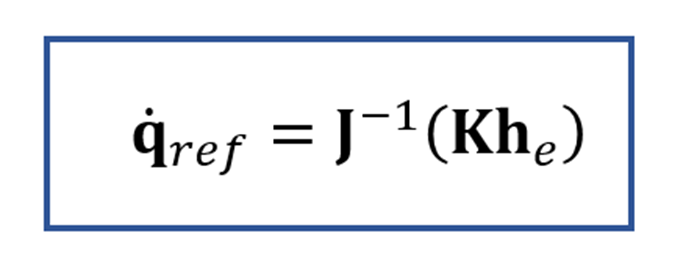

- K es una matriz de ganancias definida positiva (generalmente diagonal).

- he es el error. En este caso se calcula el error en x, y en y.

- J es la matriz Jacobiana.

Para plantear una estrategia para generar un controlador de ganancias auto-sintonizable, se partió de un razonamiento sobre la eficiencia, ya que una ganancia alta permite hacer el trayecto en menor tiempo pero puede generar sobretiro u oscilaciones y una ganancia baja puede hacer que tarde mucho el trayecto.

Con esto, la estrategia planteada se relaciona con el error, haciendo que la auto-sintonización de las ganancias permita que si el error es grande la ganancia sea grande, y cuando el error sea pequeño, la ganancia sea pequeña.

Además, inspirado por el reto del bloque anterior, se le añadio un filtro EMA, con un factor de suavizacion, ya que como se reportó con las diferentes ganancias, se pueden tener giros bruscos o una trayectoria suave, y dependiendo de lo que se busque se puede cambiar el factor alpha. Con un valor bajo se prioriza una respuesta suave, mientras que con valores alto se prioriza una respuesta rapida.

Para esto, se estableció una ganancia máxima y una ganancia mínima, como un rango de operación que le permita al robot llegar a su objetivo. Siguiendo los valores utilizados en las pruebas reportadas, se utilizó el rango de 0.5 a 2, aunque podría expandirse.

%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Ganancias para el controlador auto-sintonizable
kMax = 2;    % Ganancia maxima
kMin = 0.5;  % Ganancia minima

alpha = 0.5; % Factor de suavizacion
k_auto_prev = kMin;

for k=1:N 

    %Errores de control
    hxe(k)=hxd-hx(k);
    hye(k)=hyd-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %Calculamos la ganancia con base en el error actual
    %Cuando el error es grande la parte exponencial tiende a 0, y se
    %obtiene la ganancia máxima, y cuando el error es pequeño la parte
    %exponencial tiende a 1 y se obtiene la ganancia mínima
    k_auto = kMin + (kMax - kMin) * (1 - exp(-Error(k)));
    
    %Se aplica el filtro EMA para obtener una respuesta rapida o suave,
    %dependiendo de lo que se desee
    k_auto = (1-alpha) * k_auto_prev + alpha * k_auto;
    k_auto_prev = k_auto;

    %Matriz de Ganancias auto-sintonizable
    K=[k_auto 0;...
       0 k_auto];

    %Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %Ley de Control
    qpRef= pinv(J)*K*he;

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


Una vez aplicado el control, como se establece en la sección anterior, se continúa con la odometría para calcular la pose actual del robot diferencial, mediante la integración de las velocidades angular y lineal.

%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ xp1*ts; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ yp1*ts; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

El código siguiente corresponde a la simulación.

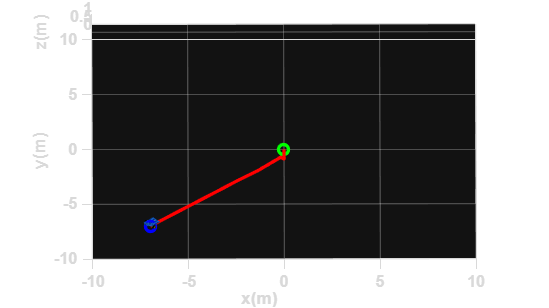

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,0,'bo','lineWidth',2); %Grafico circulo en posición deseada
H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

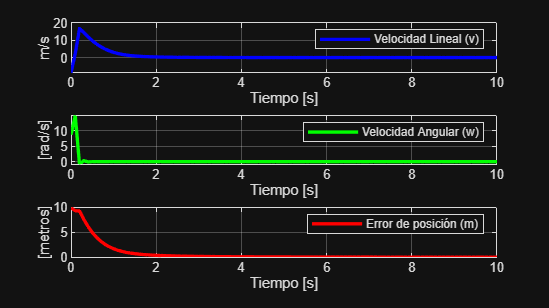


end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');

subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

